# CIC data for simulation

## 1. What data is necessary?

### Flows profile generation

The last item of the **Import** menu in the **Ephemeris** ribbon group allow to generate the **Flows profile files** From geometrical data. Inputs and ouput are CIC-CCSDS files

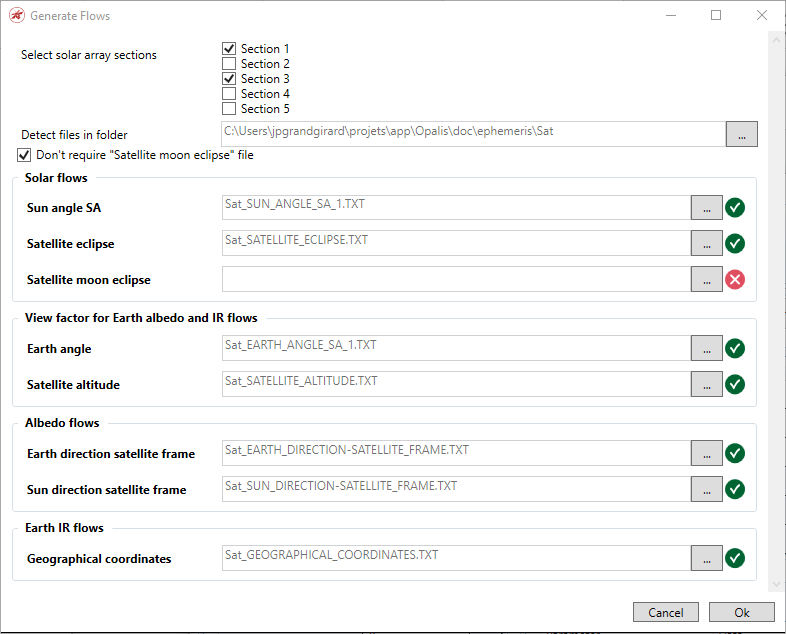

### Files specification

**Sun angle SA (required)**

Standard CIC-CCSDS MEM file with one real data column. The data represents the angle in degrees between the sun direction and the normal of the concidered surface. The default file with the auto detection is the first one with the USER_DEFINED_CONTENT defined by SUN_ANGLE_SA_1.

**Satellite eclipse (required)**

Standard CIC-CCSDS MEM file with one real data column. The data represents the eclipse ratio of the satellite (0.0 : 0% eclipsed, 1.0: 100% eclipsed (umbra)). This ratio considers only the earth. The default file with the auto detection is the first one with the USER_DEFINED_CONTENT defined by SATELLITE_ECLIPSE.

**Satellite moon eclipse (optional)**

Standard CIC-CCSDS MEM file with one real data column. The data represents the eclipse ratio of the satellite (0.0 : 0% eclipsed, 1.0: 100% eclipsed (umbra)). This ratio considers only the moon. The default file with the auto detection is the first one with the USER_DEFINED_CONTENT defined by SATELLITE_ECLIPSE_MOON. This file is not required if the *Don’t require “Satellite moon eclipse” file* control is checked.

**Earth angle (required)**

Standard CIC-CCSDS MEM file with one real data column. The data represents the angle in degrees between the earth direction and the normal of the concidered surface. The default file with the auto detection is the first one with the USER_DEFINED_CONTENT defined by EARTH_ANGLE_SA_1.

**Satellite altitude (required)**

Standard CIC-CCSDS MEM file with one real data column. The data represents the altitude of the satellite in kilometers. The default file with the auto detection is the first one with the USER_DEFINED_CONTENT defined by SATELLITE_ALTITUDE.

**Earth direction satellite frame (required)**

Standard CIC-CCSDS MEM file with 3 real data columns. The data represent the Earth direction (cosine director) in the satellite reference frame The default file with the auto detection is the first one with the USER_DEFINED_CONTENT defined by EARTH_DIRECTION-SATELLITE_FRAME.

**Sun direction satellite frame (required)**

Standard CIC-CCSDS MEM file with 3 real data columns. The data represent the Sun direction (cosine director) in the satellite reference frame The default file with the auto detection is the first one with the USER_DEFINED_CONTENT defined by SUN_DIRECTION-SATELLITE_FRAME.

**Geographical coordinates (required)**

Standard CIC-CCSDS MEM file with 2 real data columns. The data represents the longitude and latitude of the satellite in degrees. The default file with the auto detection is the first one with the USER_DEFINED_CONTENT defined by GEOGRAPHICAL_COORDINATES.

### Power profile file

This file describes the spacecraft power consumption in Watt. This file is used when when **Power consumption mode** is setted to **Profil**.

This file is intended to be a CIC SATELLITE_CONSUMED_POWER standard file but every MEM file with exactly one REAL column can be used.

## 2. Creating the simulink

The simulink file created to generate the data is: ***CICdatapowerfrompropagator.slx***

But first, to initialize it, we need to configure some parameters:

clear
close

%Initialisation of date
date.year=2024;
date.month=9;
date.day=21;
date.hour=12;
date.minutes=0;
date.seconds=0;

%Orbit: Initialisation of Keplerian parameters
orbit.R_earth=6378e3;
orbit.altitude=300e3;
orbit.a = 6678e3;       %semimajor axis [m]
orbit.e = 0.001;        %eccentricity
orbit.i = 98;           %inclination [degrees]
orbit.O = 0;            %Right ascension of the right ascending node [degrees] 
orbit.o = 0;            %Argument of the perigee [degrees]                      
orbit.nu = 0;           %True anomaly [degrees]
%In this case, RAAN=orbit.O is close to the Beta angle.

%time step  
TimeStep = 10;        %fixed-step size in solver, Default time step=0.25
Torbit=2*pi*sqrt((orbit.a/1e3)^3/(3.986004418E5));
N_orbits = 2;           %number of orbits to be simulated
%Time spent performing the simulation in seconds (one orbit is ~5400 s):
t_sim = N_orbits*Torbit;
MODE=2;


To open the simulation

%CICdatapowerfrompropagator

To get the data out from the simulation

out=sim('CICdatapowerfrompropagator')

out =   Simulink.SimulationOutput:

            Earth_angle: [1x1 timeseries] 
        Earth_direction: [1x1 timeseries] 
                     LL: [1x1 timeseries] 
           Sun_angle_SA: [1x1 timeseries] 
          Sun_direction: [1x1 timeseries] 
                   T_JD: [1x1 timeseries] 
                    alt: [1x1 timeseries] 
                eclipse: [1x1 timeseries] 
                   tout: [1087x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


Now we can run the script to convert the data to the CIC format

NOTE: Be sure to be on the folder above the CICData folder where the CIC files will be created.

CIC_writer_EPS

and finally, copy these files to the OPALIS directory

NOTE: Be sure to be on the folder above the CICData folder where the CIC files were created.

The destination folder can be changed to your own folder.

copyfile("./CICData/data_earth_angle.txt","C:\CNES\OPALIS\IonSat")
copyfile("./CICData/data_earth_dir.txt","C:\CNES\OPALIS\IonSat")
copyfile("./CICData/data_eclipse.txt","C:\CNES\OPALIS\IonSat")
copyfile("./CICData/data_geo_latlon.txt","C:\CNES\OPALIS\IonSat")
copyfile("./CICData/data_sat_alt.txt","C:\CNES\OPALIS\IonSat")
copyfile("./CICData/data_sun_angle.txt","C:\CNES\OPALIS\IonSat")
copyfile("./CICData/data_sun_dir.txt","C:\CNES\OPALIS\IonSat")